# Análise de sinais de voz

%%% Incia o ambiente matlab para uma sessão de análises

clear; clc; close all;

%%% Carrega o trabalho feito anteriormente e gravado no arquivo Voz.mat

load('Voz.mat') 


## Vissualizando o material que temos

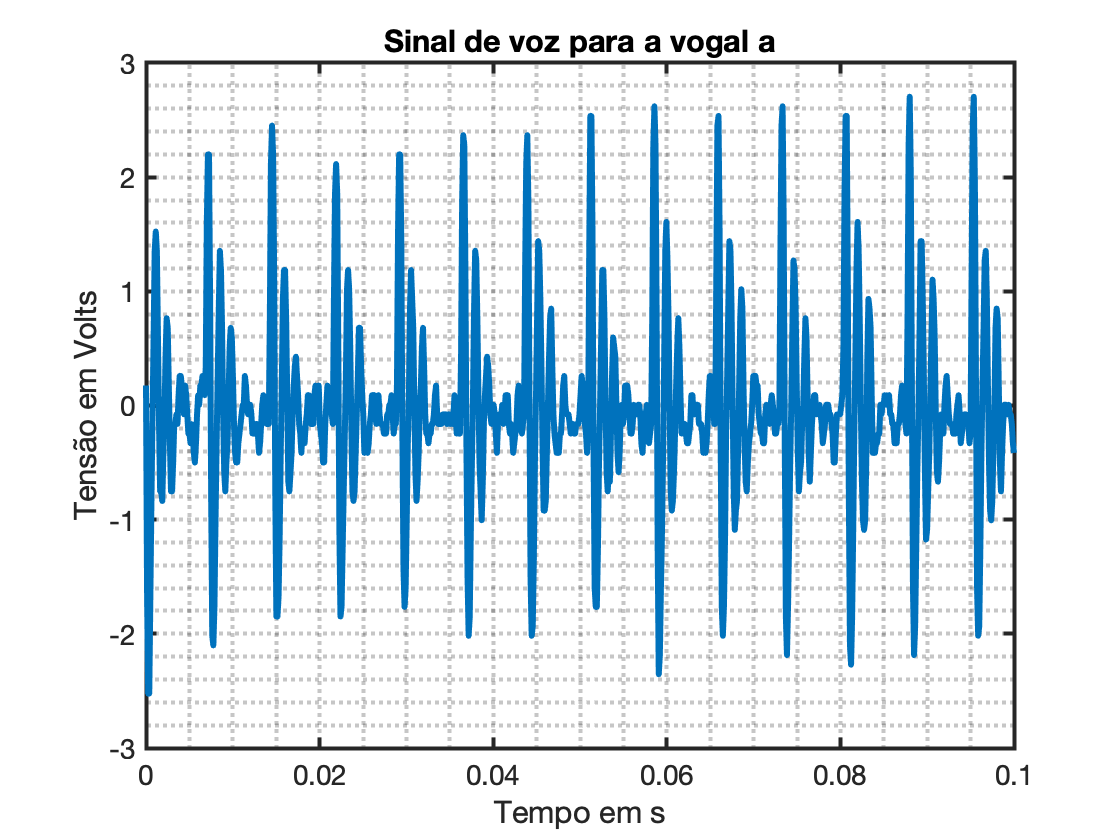


% Cria uma figura para a análise temporal

plot(t,Vp);
title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

%%% modifica parâmetros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

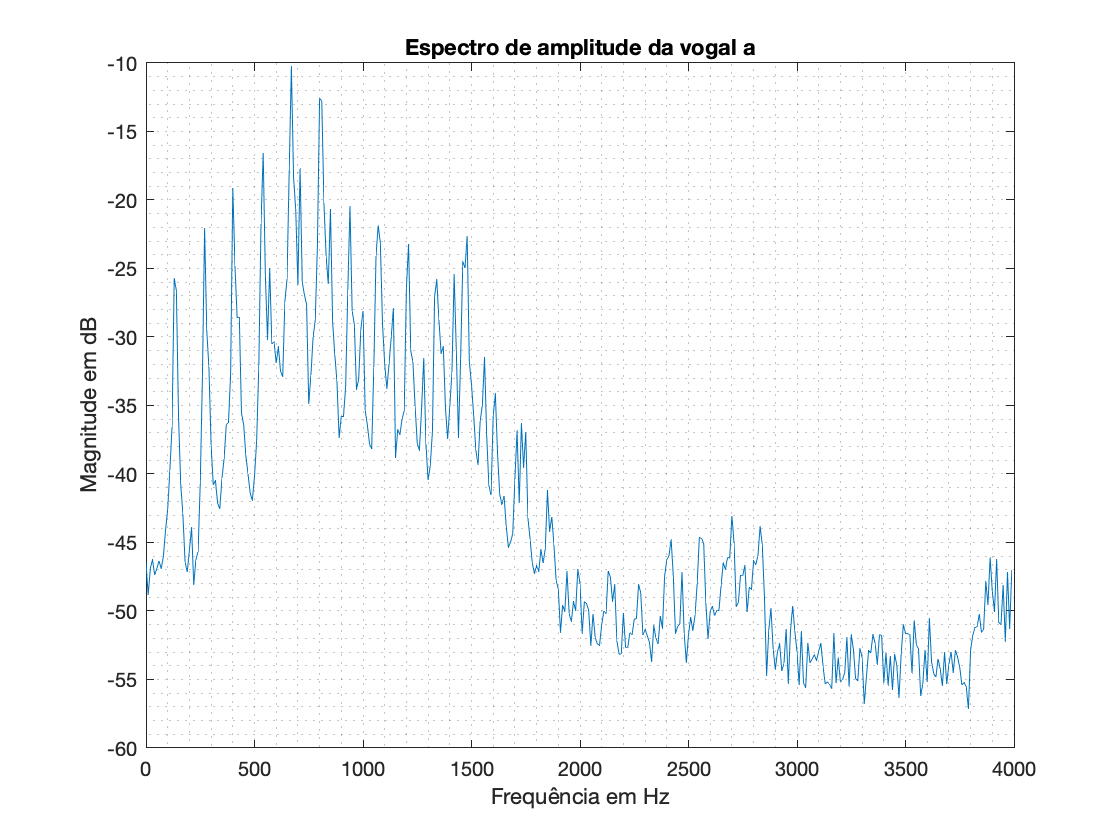


% Cria uma figura para a análise em frequência

plot(frequencia,Y0);
title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor

## Modifica parâmetros do gráfico

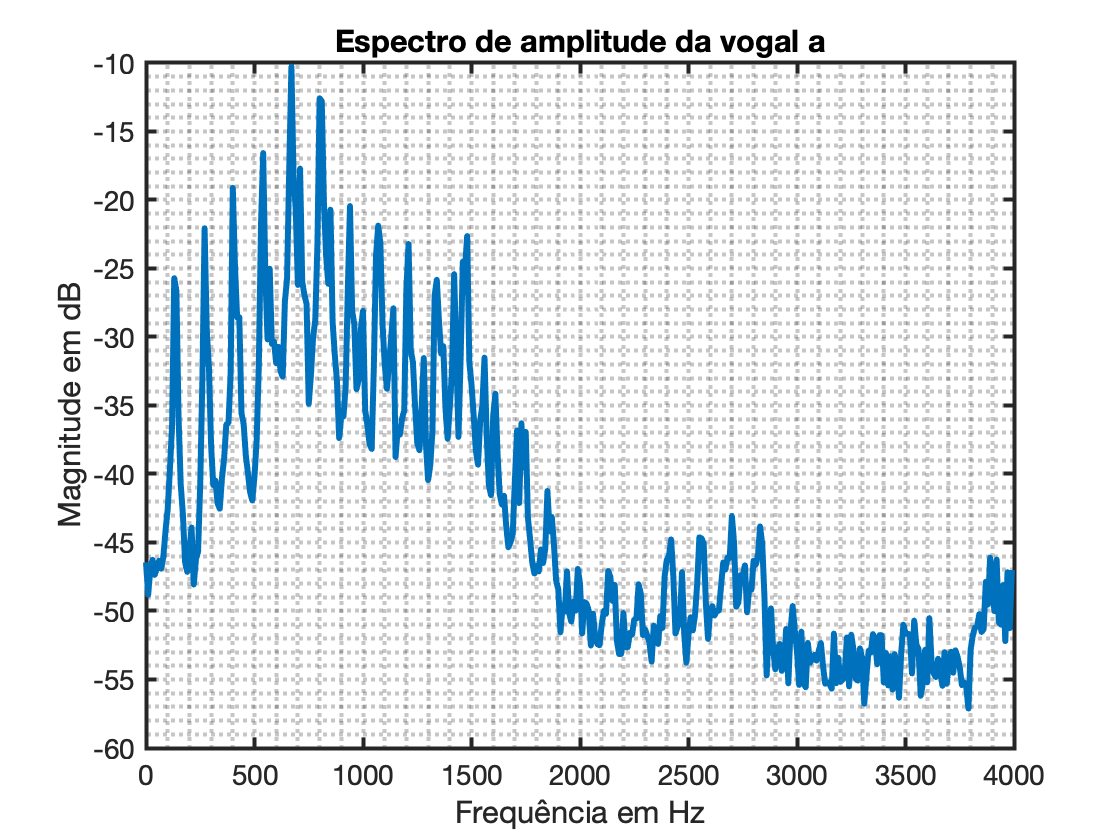

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

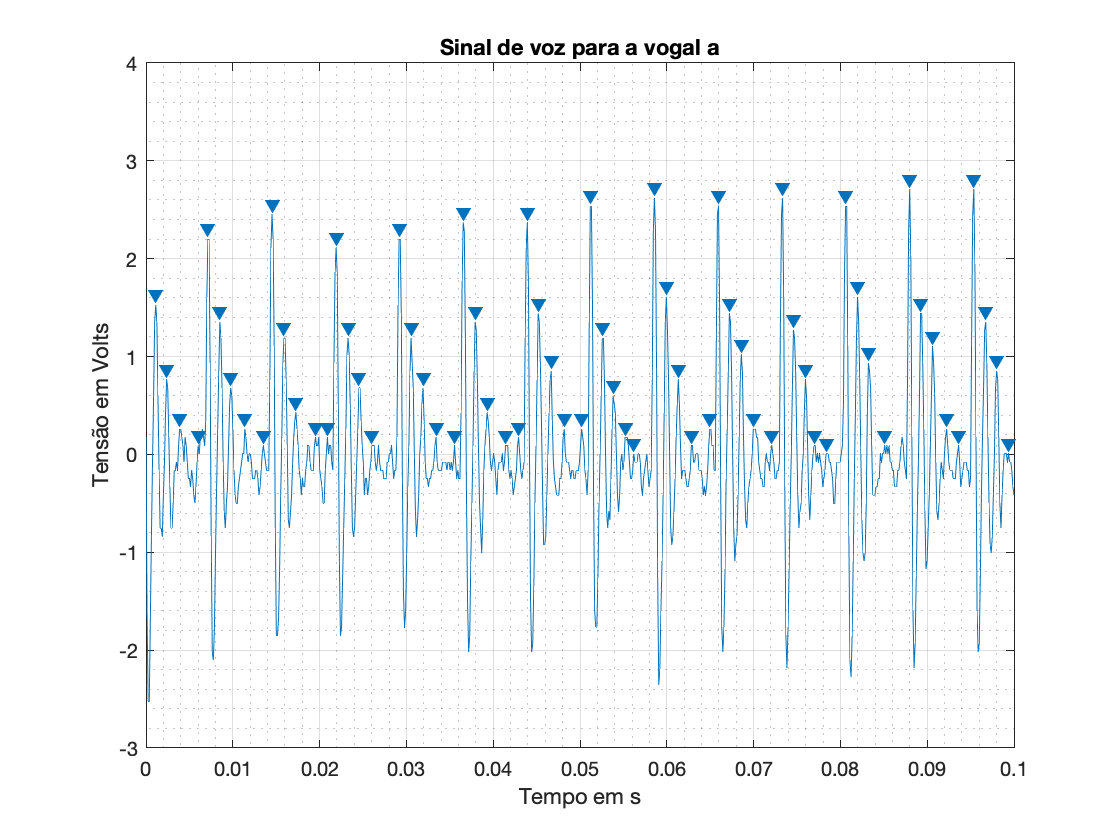


%%% Analisando os parâmteros graficamente

ti = 0.001126;  % começo do primeiro período inteiro
tf = 0.09537;   % fim do último período inteiro

T = (tf-ti)/13; % valor médio dentre os 13 períodos
f = inv(T);     % frequência associada a vibração gerada

findpeaks(Vp,t,'MinPeakDistance',0.001);

[vt,tp]=findpeaks(Vp,t,'MinPeakDistance',0.001);

Tm =mean(diff(tp));

title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

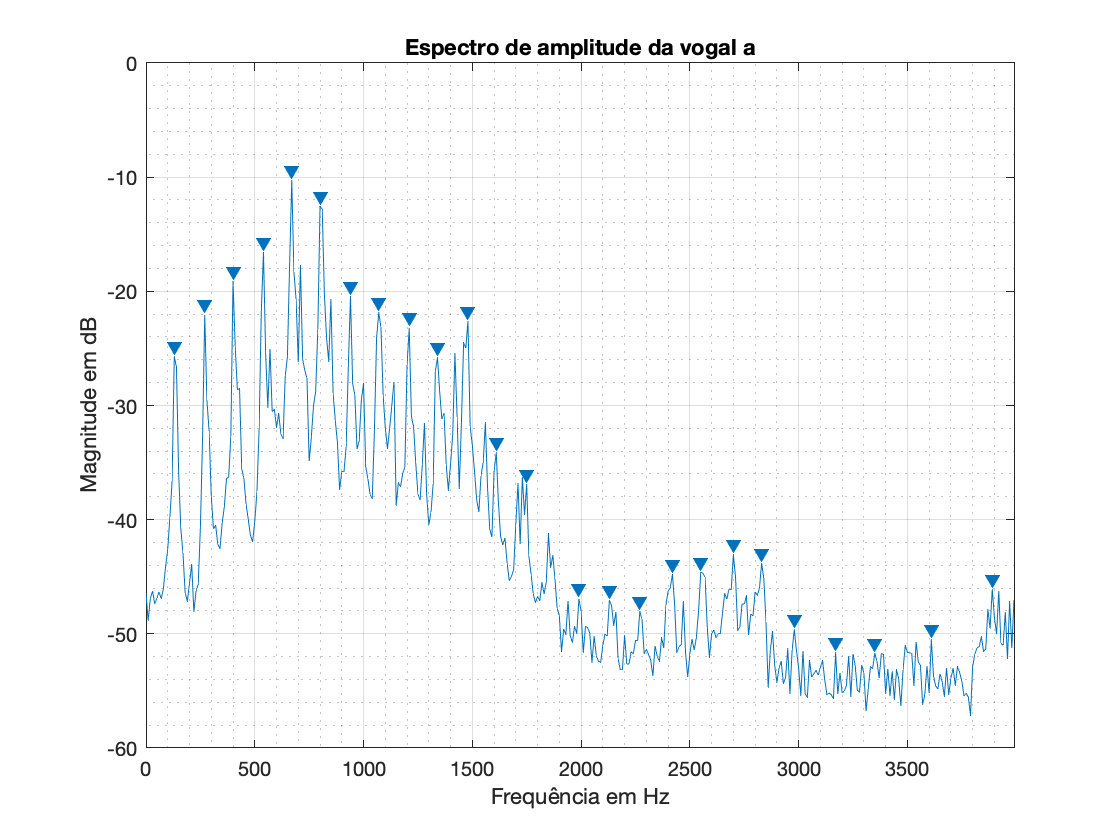


findpeaks(Y0,frequencia,'MinPeakDistance',0.9*f);

title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor


[Md,fp]=findpeaks(Y0,frequencia,'MinPeakDistance',0.9*f);



## Harmônicas

H(1) = 130;
H(2) = 270;
H(3) = 400;
H(4) = 540;
H(5) = 670;
H(6) = 800;
H(7) = 940;
H(8) = 1070;

delta  =  diff(H);

%%% Valor médio da harmônica

Hm = mean(delta);

%%%% Formantes

FRM(1) = 670;
FRM(2) = 1480;
FRM(3) = 2700;



## Analisando o sinal de Voz

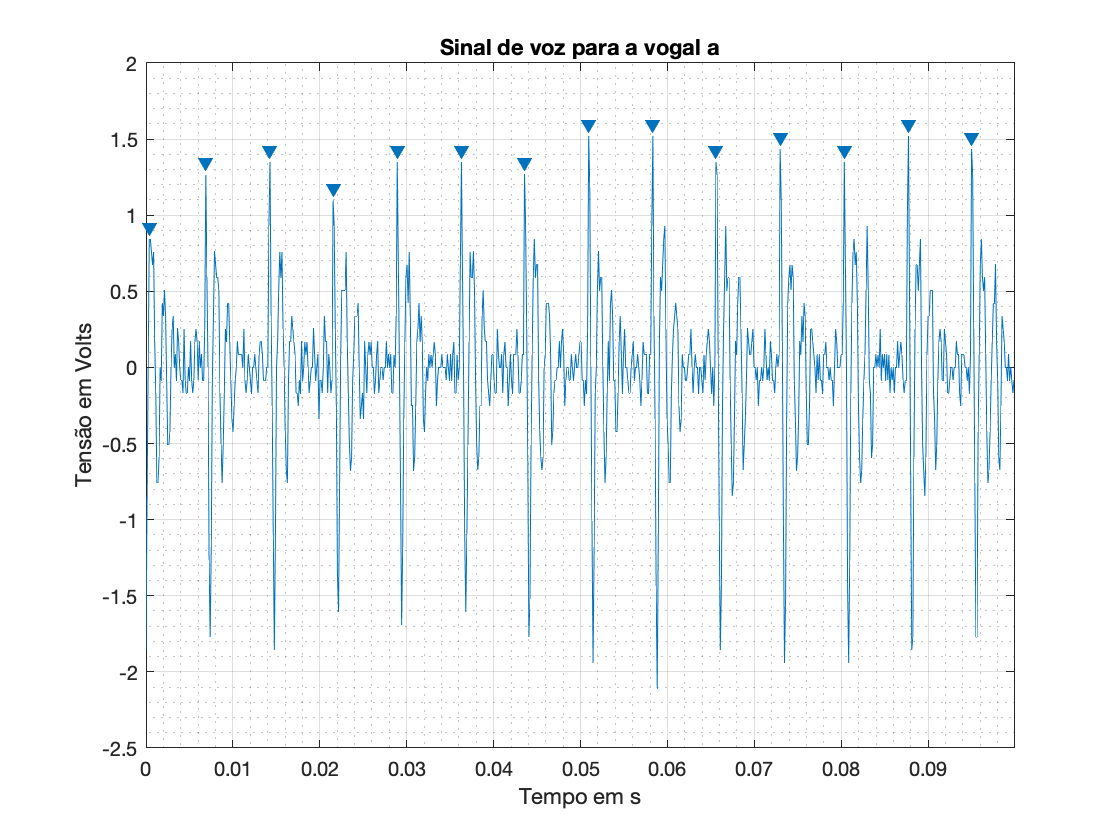

findpeaks(diff(Vp),t(1:end-1),'MinPeakDistance',0.001,'MinPeakDistance',0.005);
[vt,ip] = findpeaks(diff(Vp),t(1:end-1),'MinPeakDistance',0.001,'MinPeakDistance',0.005);

title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid minor

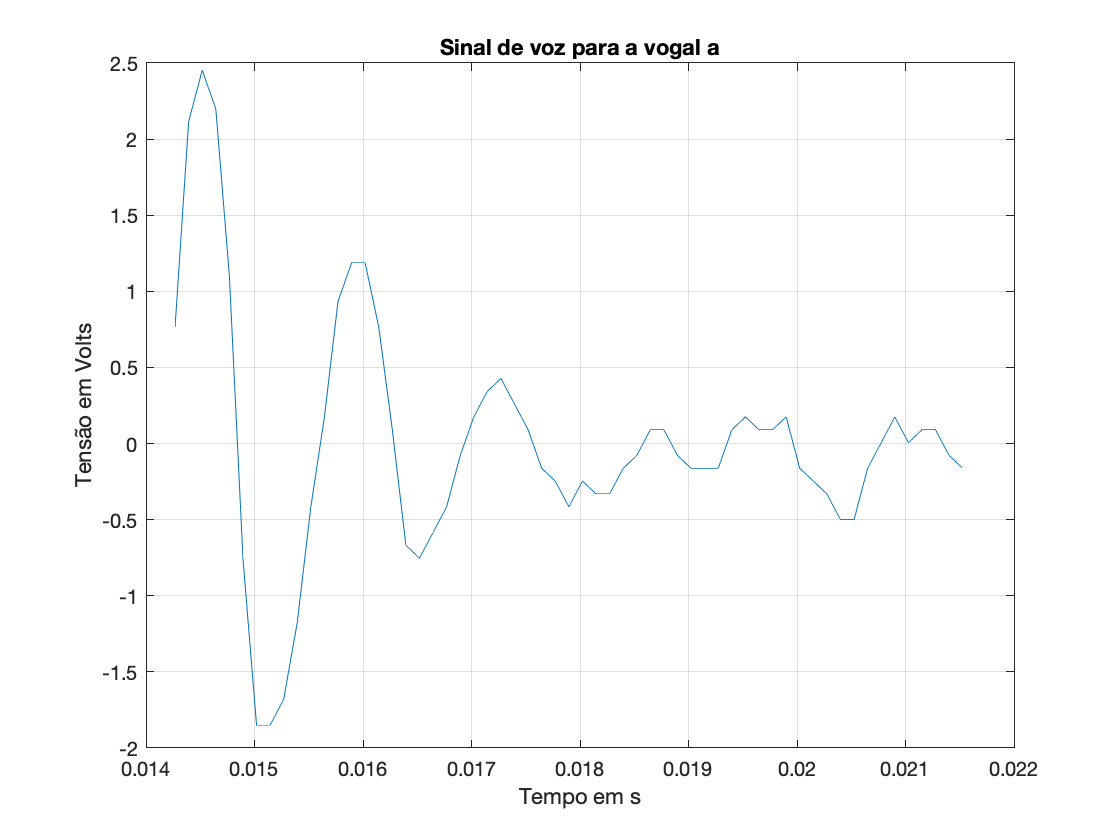


inicio =  find(t==ip(3));
fim    =  find(t==ip(4));

plot(t(inicio:fim),Vp(inicio:fim));
title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid 


X = t(inicio:fim) - t(inicio);
Y = Vp(inicio:fim);

[vexp,texp] = findpeaks(Y,X,'MinPeakDistance',0.001);

f = fit(texp(1:3)',vexp(1:3),'exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       2.851  (1.041, 4.66)
       b =      -575.8  (-1290, 138.8)

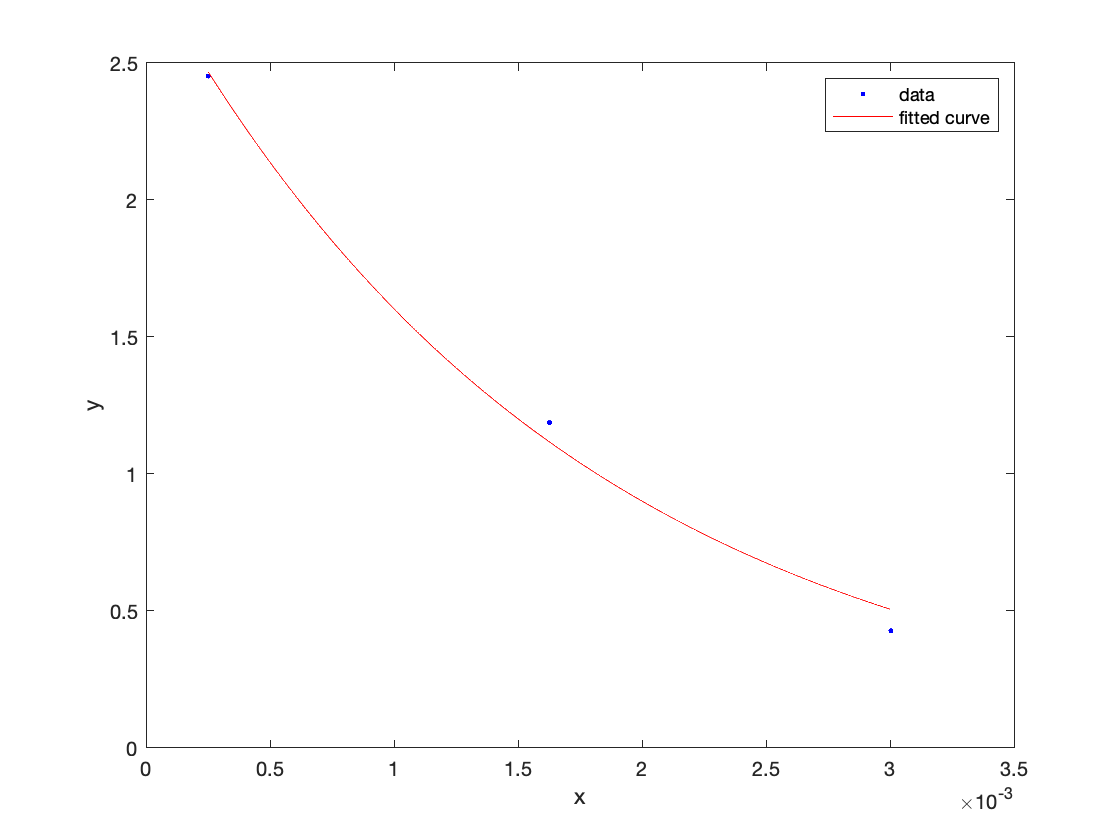

plot(f,texp(1:3)',vexp(1:3))

## Otimizando


x=[0 2.851 -575 730]';

% Plot the original and experimental data.

Y_new =  x(1) + x(2).*exp(x(3).*X).*sin(2*pi*x(4).*X)

Y_new =          0    1.4407    2.2515    2.2711    1.5996    0.5331   -0.5520   -1.3243   -1.5916   -1.3406   -0.7168    0.0406    0.6842    1.0341    1.0236    0.7042    0.2141   -0.2752   -0.6155   -0.7236   -0.5978   -0.3077    0.0368    0.3240    0.4744    0.4609    0.3095    0.0845   -0.1359   -0.2856   -0.3286   -0.2662   -0.1315    0.0250    0.1530    0.2174    0.2073    0.1357    0.0326   -0.0666   -0.1323   -0.1491   -0.1184   -0.0560    0.0151    0.0720    0.0995    0.0931    0.0594    0.0122


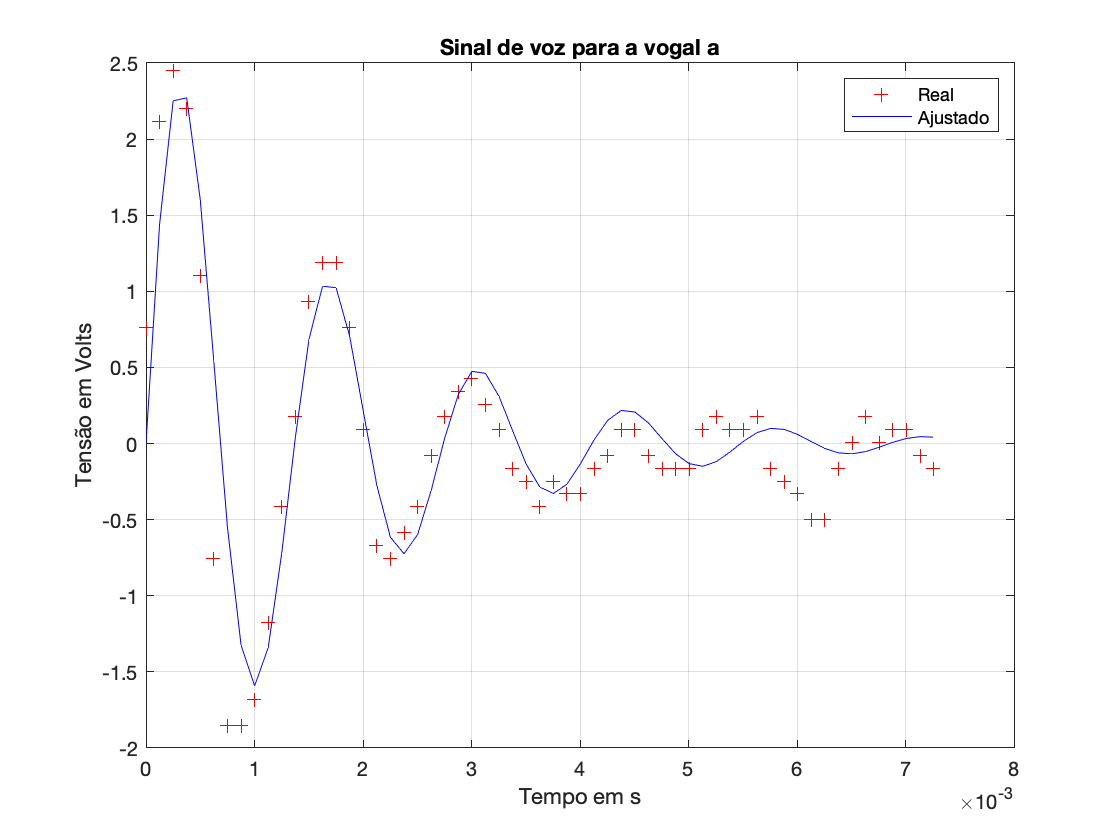


plot(X,Y,'+r',X,Y_new,'b')
title('Sinal de voz para a vogal a');
xlabel('Tempo em s');
ylabel('Tensão em Volts'); 
grid 
legend('Real','Ajustado')

## Analisando as respectivas funções de transferência

% Transformando a função temporal em uma função de laplace

x=[0 2.851 -575 730]';
Y_new =  x(1) + x(2).*exp(x(3).*X).*sin(2*pi*x(4).*X)

Y_new =          0    1.4407    2.2515    2.2711    1.5996    0.5331   -0.5520   -1.3243   -1.5916   -1.3406   -0.7168    0.0406    0.6842    1.0341    1.0236    0.7042    0.2141   -0.2752   -0.6155   -0.7236   -0.5978   -0.3077    0.0368    0.3240    0.4744    0.4609    0.3095    0.0845   -0.1359   -0.2856   -0.3286   -0.2662   -0.1315    0.0250    0.1530    0.2174    0.2073    0.1357    0.0326   -0.0666   -0.1323   -0.1491   -0.1184   -0.0560    0.0151    0.0720    0.0995    0.0931    0.0594    0.0122


clear('tf')                 % apaga a variável que impede o cálculod a função de transferência
                            % no futuro melhor mudar o nome da variável
k  = x(2)*2*pi*x(4);
p1 = x(3) + j*2*pi*x(4);
p2 = x(3) - j*2*pi*x(4);
z  = [];

Gvoz = zpk(z,[p1 p2],k)

Gvoz =
 
           13077
  ------------------------
  (s^2 + 1150s + 2.137e07)
 
Continuous-time zero/pole/gain model.



Tn = 1/x(4);
Ts = Tn/20;
fs = 1/Ts;

[Zd,Pd,Kd] = bilinear(z,[p1 p2]',k,fs)

Zd =     -1
    -1


Pd =    0.9159 - 0.2951i
   0.9159 + 0.2951i


Kd = 1.4408e-05

[Nd,Dd] = zp2tf(Zd,Pd,Kd)

Nd = 	1.0e+-4 *

    0.1441    0.2882    0.1441


Dd =     1.0000   -1.8318    0.9260


Gvozd = tf(Nd,Dd,Ts)

Gvozd =
 
  1.441e-05 z^2 + 2.882e-05 z + 1.441e-05
  ---------------------------------------
           z^2 - 1.832 z + 0.926
 
Sample time: 6.8493e-05 seconds
Discrete-time transfer function.



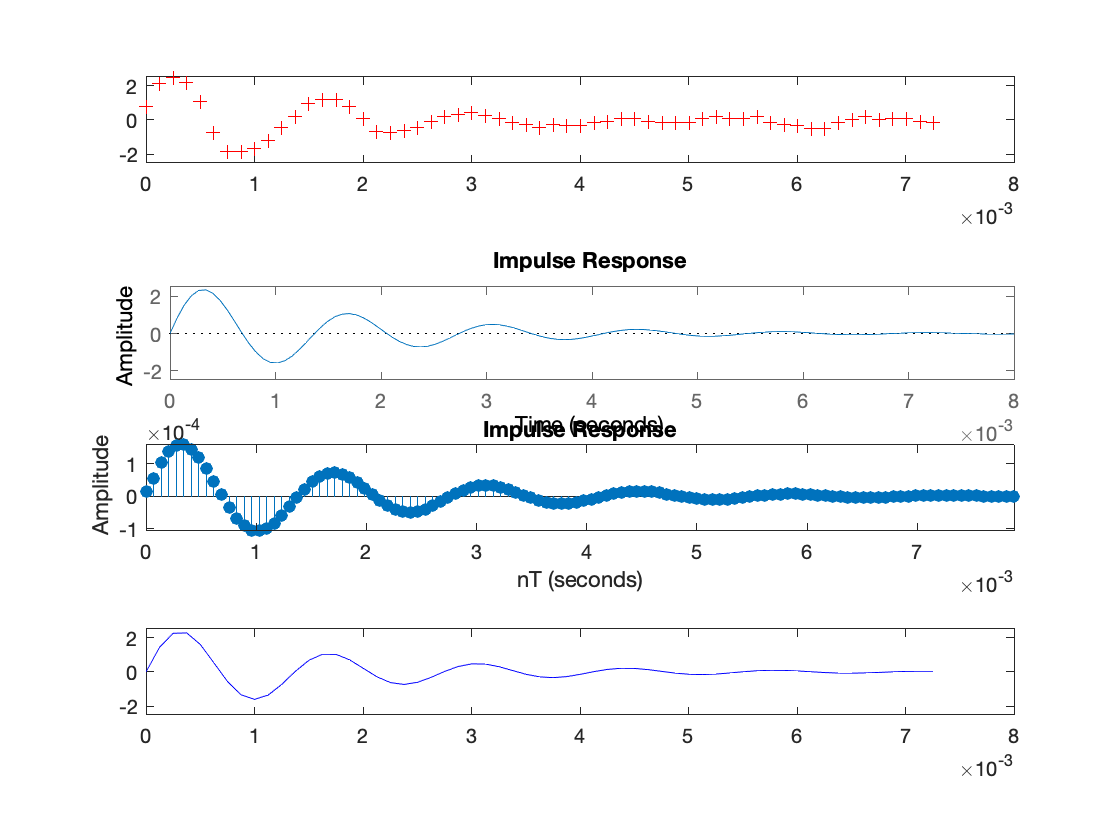

subplot(4,1,2); 
impulse(Gvoz);
axis([0 8e-3 -2.5 2.5])
subplot(4,1,3); 
impz(cell2mat(Gvozd.numerator),cell2mat(Gvozd.denominator),(8e-3/Ts),fs)
subplot(4,1,1); 
plot(X,Y,'+r')
axis([0 8e-3 -2.5 2.5])
subplot(4,1,4); 
plot(X,Y_new,'b')
axis([0 8e-3 -2.5 2.5])

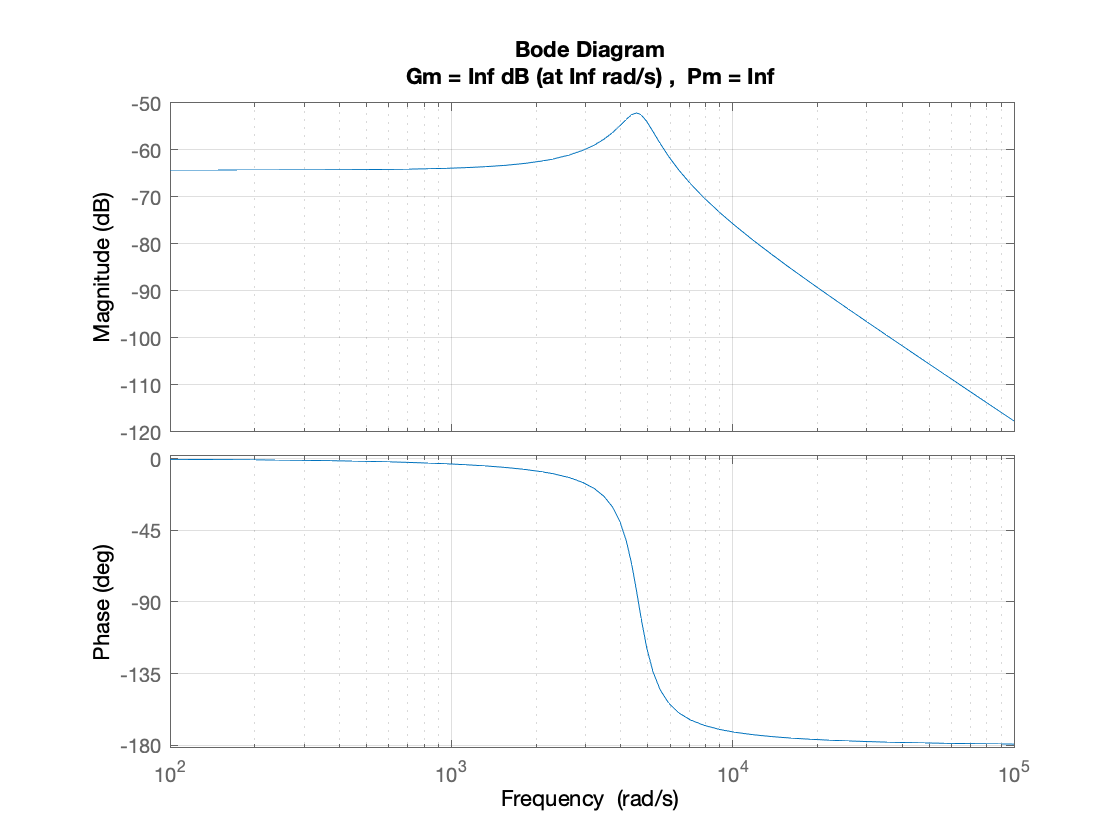

figure()
margin(Gvoz);
grid;

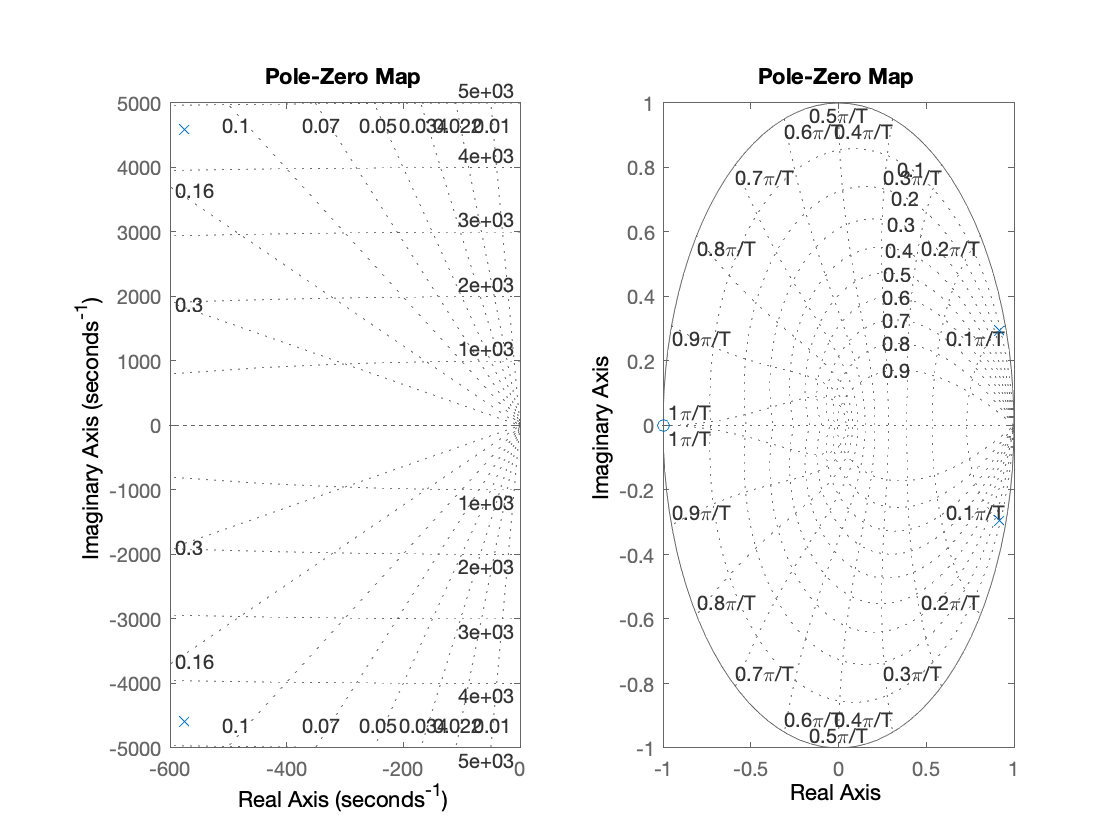


figure()

subplot(1,2,1)
pzmap(Gvoz);
grid;

subplot(1,2,2)
pzmap(Gvozd);
grid;